n = 30;

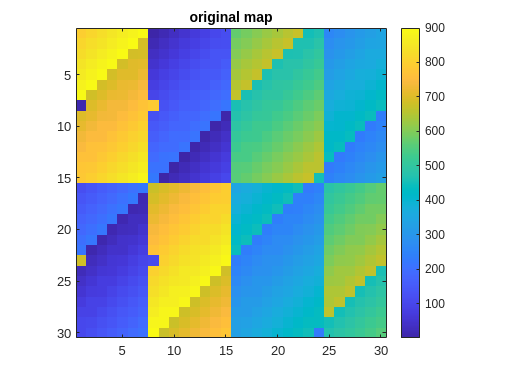

% and suppose we have a map that we want to use to generate noise
% this map is not distributed according to a guassian, but it 
% has a clear spatial pattern that we want to preserve
% map1 = ((1:n)' + (1:n)).^2 + n*n*(1:n)/2
map1 = magic(n); 
imagesc(map1); title('original map'); % spatial pattern
axis square; colorbar;

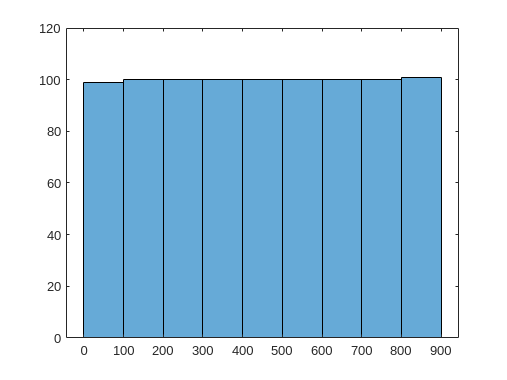

histogram(map1) % distribution

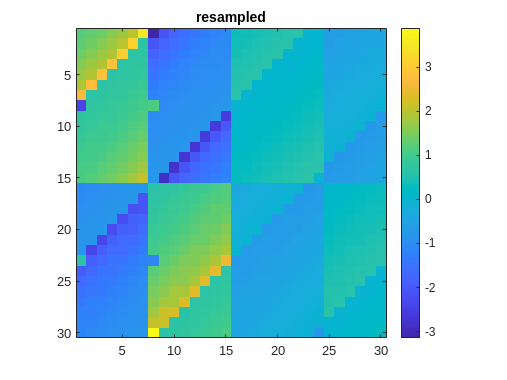

%% this is how we replace the data in map1 with noise distributed following
% a gaussian, whilst maintaining the same spatial pattern
sortNoise = sort(normrnd(0, 1, numel(map1), 1)); % make noise
% sortNoise = sort(noise(:)); % sort it
[~, idx] = sort(map1(:)); % get the spatial pattern of the template map
clear noise2;
noise2(idx) = sortNoise; % order the noise according to the spatial pattern
noise2 = reshape(noise2, size(map1)); %make is the correct shape
imagesc(noise2); title('resampled');
axis square; colorbar

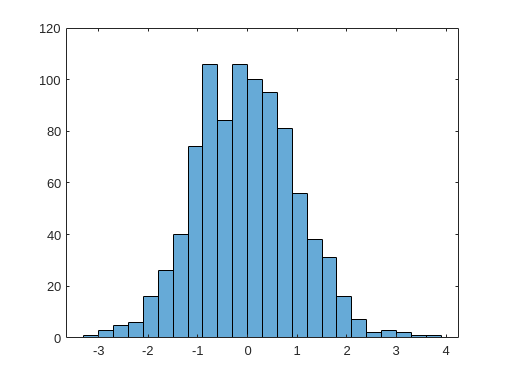

histogram(noise2)

% you can see that noise2 is normally distributed and has the same spatial
% pattern as the template map, map1

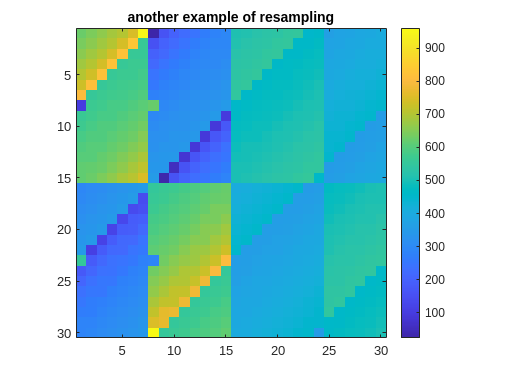

noise3 = resampleMatrix(map1, "gaussian", 'randParams', [n^2/2, n^2/6]);
imagesc(noise3); title('another example of resampling');
axis square; colorbar

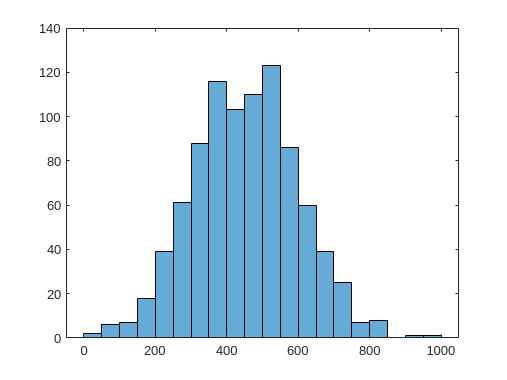

histogram(noise3)